# How to: A short Guide on getting started with `IFDIFF`

The software package `IFDIFF` deals with the solution and algorithmic generation of sensitivities in ordinary differential equations with implicit (state-dependent) non-differentiabilites (“switches”) in the right-hand side that is given as MATLAB program code with non-differentiable operators such as `min`, `max`, `abs`, `sign`, as well as `if`-branching. `IFDIFF` automatically generates only necessary switching functions, outputs them as MATLAB code, and detects switching points accurately up to machine precision.

`IFDIFF` handles multidimensional state and parameter vectors and can be transparently used in existing code, as it generates `sol` solution structures compatible to the `MATLAB` ode solvers. No modifications to the right hand side or manual processing are necessary. A single preparation call is sufficient.

For a more in-depth explanation of the package please visit [`IFDIFF`](https://andreassommer.github.io/ifdiff/).

## 0) First Run Prerequisites

If you are reading this, it means that you successfully added the `IFDIFF` toolbox to your local machine. That's great! It means, you can proceed with the setup of the software itself.

Before using `IFDIFF` for the first time, make sure to run the `make_mtreeplus` script by typing

into the terminal. This has to be done only once. It will generate a modified copy of MATLAB's own parser class `mtree`, which `IFDIFF` heavily relies on. Make sure this has been done properly, as otherwise further steps won't be possible.

## 1) Before each Session

Once done, initialize the paths to all source functions and files by typing

initIFDIFF()

into the terminal. It is important to do this before **every** session, as this adds all necessary `IFDIFF``-`source files to the current path.

## 2) A first Integration with `IFDIFF`

To compute an integration with `IFDIFF` first, a (switched) ODE is needed in the form of a separate `MATLAB` function file that encodes the **Right-Hand-Side** (RHS) of the **Initial-Value-Problem** (IVP). For demonstration purposes the following switched problem is chosen:


$$\dot{x} = f(t,x,p) = \pmatrix{f_1(t,x,p) \cr f_2(t,x,p)} \\ \\

f_1(t,x,p) = 0.01 \cdot t^2 + x_2^3 \hspace{20pt} f_2(t,x,p) = \begin{cases} 
0 & \text{if} & x_1 < p \\ 5 & \text{if} & p \leq x_1 < p +0.5 \\ 0 & \text{if} & x_1 \geq p + 0.5 \end{cases}$$


With the initial value:

$x(0) = (1,0)^T \hspace{20pt} \text{and the parameter} \hspace{20pt} p=5.437$.

The RHS is found in [**canonicalExampleRHS.m**](matlab:open('..\examples\canonicalExample\canonicalExampleRHS.m'))

type canonicalExampleRHS.m


function dx = canonicalExampleRHS(t,x,p)

dx = zeros(2,1);
dx(1) = 0.01 * t.^2  +  x(2).^3;

if x(1) < p(1) 
    dx(2) = 0;
else
    if x(1) < p(1) + 0.5
        dx(2) = 5;
    else
        dx(2) = 0;
    end
end

end





Then, `IFDIFF` can be used by following the simple steps:

### Initialization

Initialize all necessary parameters for the integration:

t0 = 0;
tf = 20;
timeinterval = [t0,tf];
initstates   = [1  0 ];
p            = 5.437;

### Preprocessing of the RHS Function

`IFDIFF` uses its instance of the `mtree` class to deconstruct the code of the RHS function, replacing the conditions in `if` statements with **ctrlif**, now being able to monitor when a switch occurs during integration (with minimal user interaction). Just pick your favorite MATLAB integrator such as `@ode45` and pass it to the preprocessor (`prepareDatahandleForIntegration()`):

integrator = @ode45;
odeoptions = odeset('AbsTol', 1e-20, 'RelTol', 1e-12);
filename = 'canonicalExampleRHS';      % name of the file in which the RHS can be found 
dhandle = prepareDatahandleForIntegration(filename, 'integrator', integrator, 'options', odeoptions);

### Integration and Extraction of Solution Array

From here on a call to the function `solveODE()` handles integration, dynamically dealing with the generation of switching functions as well as the computation of the switching points!

sol_ifdiff = solveODE(dhandle, timeinterval, initstates, p);

**Note:** `solveODE()` returns a solution object which is compatible with MATLAB's own `deval()` function to extract the solution at distinct times.

T = 0:0.1:20;
sol = deval(sol_ifdiff, T);

## 3) `IFDIFF` is Accurate

For demonstration purposes, solutions to the above example computed by `IFDIFF`, the plain `MATLAB`-approach and an accurate Euler integration are compared. As can be seen, `IFDIFF` manages to identify the two switching points and correctly treats them, whereas the unmodified `@ode45` (that doesn't track switches) steps over both.

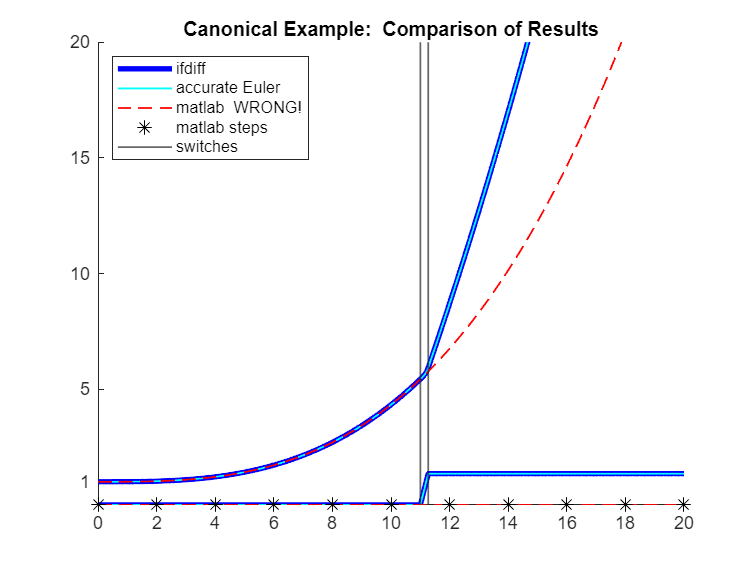

sol_matlab = integrator(@(t,x) canonicalExampleRHS(t,x,p), timeinterval, initstates, odeoptions);
N_euler =3000000;
[T, Y_euler, Y_matlabsolver, Y_ifdiff] = run_accurate_euler(N_euler, t0, tf, initstates, p, @canonicalExampleRHS, sol_matlab, sol_ifdiff);
plot_canonical_comparison(544, tf, T, Y_ifdiff, Y_euler, Y_matlabsolver, sol_matlab, sol_ifdiff, 20);

## 4) Computing Derivatives

`IFDIFF` supports the computation of first order derivatives of the solution function with respect to the initial values and parameters. The resulting matrices of partial derivatives are called sensitivities and currently three different computational methods are supported (the most accurate being the **Variational Differential Equations **(VDE)). This can be accomplished by using `IFDIFF``'`s function `generateFDstep()` combined with `generateSensitivityFunction()`.

dim_y = size(sol_ifdiff.y, 1);
dim_p = length(p);
FDstep = generateFDstep(dim_y, dim_p);
integrator_options = odeset('AbsTol', 1e-14, 'RelTol', 1e-12);

Sensitivities w.r.t. initial values and parameters:

sensitivities_function_VDE = generateSensitivityFunction(dhandle, sol_ifdiff, FDstep, 'integrator_options', integrator_options);

Here is a short list of possible arguments to configure `generateSensitivityFunction()`.

T = 0:0.001:20;
sens = sensitivities_function_VDE(T);
disp(sens);

  1×20001 struct array with fields:

    t
    Gy
    Gy_intermediate
    Uy
    Gp
    Gp_intermediate
    Up



Since `sens` is a struct-array, the sensitivity data can be extracted in the following way: (As an example, the derivative of the first variable with respect to the initial value of the first variable is extracted)

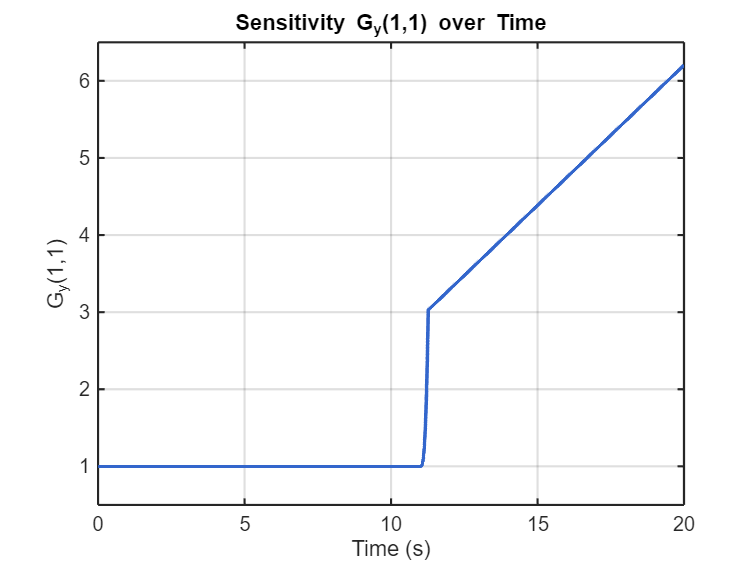

Gy11 = arrayfun(@(x) x.Gy(1, 1), sens);
figure(2000);
plot(T, Gy11, 'LineWidth', 2, 'Color', [0.2 0.4 0.8]);
grid on;
xlabel('Time (s)', 'FontSize', 12);
ylabel('G_{y}(1,1)', 'FontSize', 12);
title('Sensitivity G_{y}(1,1) over Time', 'FontSize', 14);
set(gca, 'FontSize', 11, 'LineWidth', 1.2);
ylim([0.5 6.5]);
xlim([0 max(T)]);
box on;

## 5) Further Capabilities of `IFDIFF`

Besides the fundamental functionality as shown above, `IFDIFF` offers further tools and capabilities, to enhance the modeling experience for ODEs. 

### 5.1) State Dependent Jumps

Normally, the way ODEs are formulated, it is not possible to include information about **jumps** of the solution function in the RHS function file. However, being able to include conditional jumps into an IVP description often yields a drastic simplification of the underlying problem to be solved and (if treated correctly), cuts the computational load.

`IFDIFF` offers a convenient workaround via the use of `ifdiff_jumpif` and `ifdiff_update` in the RHS function file, treating the jumps just like any other switch plus ensuring the correct computation of the sensitivities (derivatives). Here, we see an example integration of the height, velocity and energy of a bouncing ball.

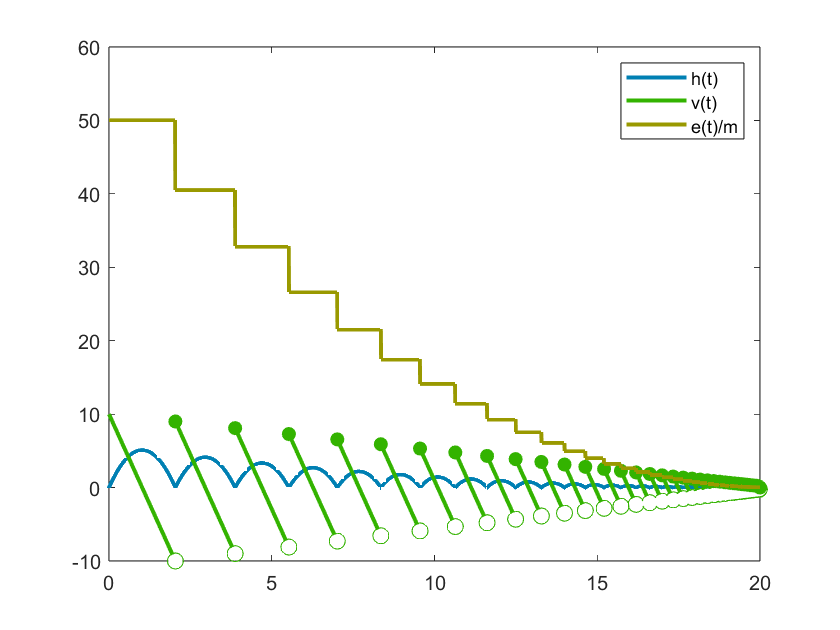

A proper introduction to this feature can be found in [**StateJumpExample.mlx**](matlab:open('..\examples\liveExamples\StateJumpExample.mlx')).

### 5.2) Filippov Trajectories

When integrating a switched system, rapid switching behavior can occur, if the vector fields of two different conditional versions of the RHS point towards each other. An unmodified integrator (such as Euler or `@ode45`) will simply trigger a switch in every step and therefore oscillate around the switching space (switching manifold). Behavior as such is extra detrimental for integrators with adaptive step size (e.g. `@ode45`), since every step is ill-conditioned, resulting in extremely small steps, long computational times and numerically unusable results.

`IFDIFF` implements a solution to this issue by computing a fitting convex combination of the two neighboring versions of the RHS. Using this new RHS, any integrator can just glide along the switching manifold, making the use of adaptive large steps possible again. A nice example to this is the switched three species Predator-Prey system visualized here:

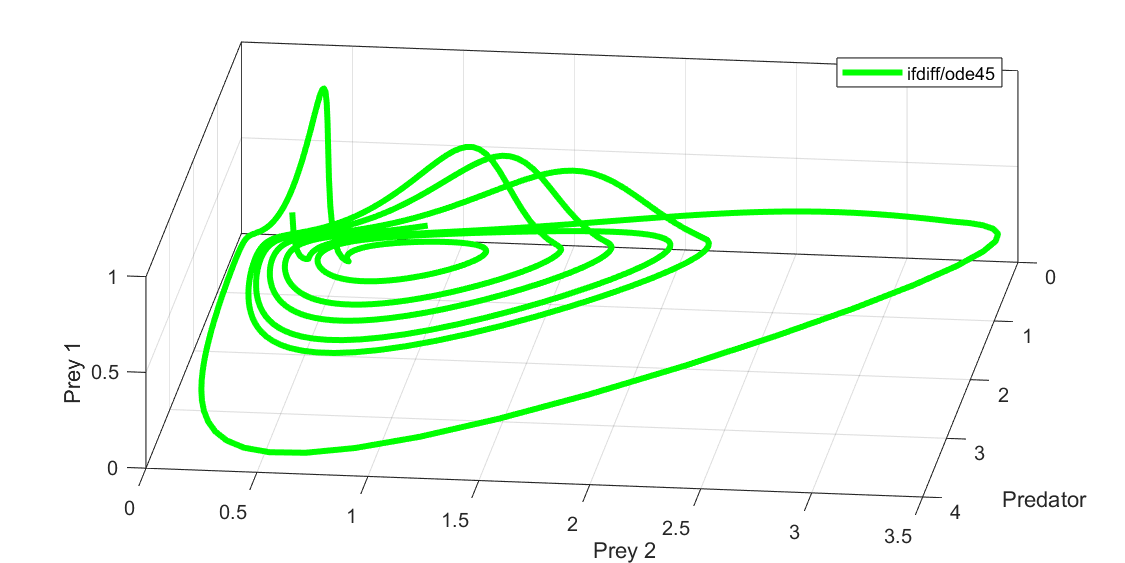

Details can be found in [**FilippovLive.mlx**](matlab:open('..\examples\liveExamples\FilippovLive.mlx')).